imds = imageDatastore ("Face_Database/", "IncludeSubfolders",true, 'LabelSource',"foldernames");  
deepNetworkDesigner

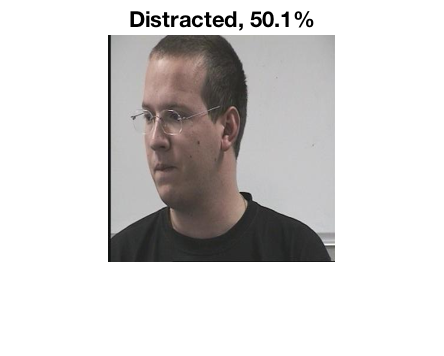


I = imread("personne01136-15+45.jpg");
I = imresize(I, [227 227]); 

[YPred,probs] = classify(trainedNetwork_1,I);
imshow(I)
label = YPred;
title(string(label) + ", " + num2str(100*max(probs),3) + "%");